addpath(genpath('./bm3d'));

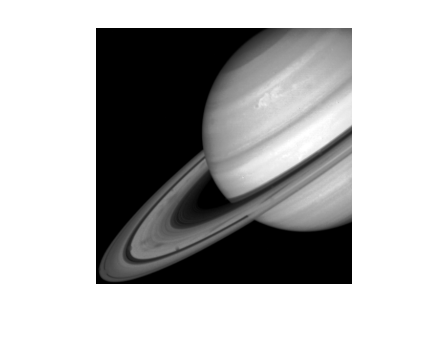

imagename = 'org_sat.png';
peak=0.5;
[org_img,y]=loading(imagename,peak);
imshow(org_img);

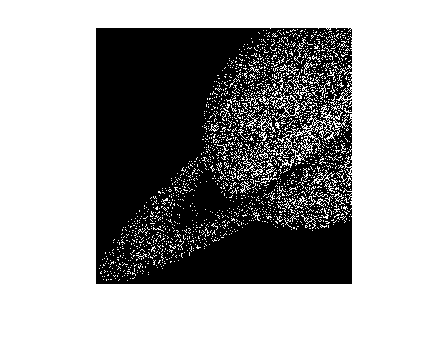

imshow(y);

disp(getPSNR(org_img,y));

    6.9532



y_col=y(:);
dim=size(y_col,1);
u_0=zeros(dim,1);
v_0= y(:);
lambda=0.25;


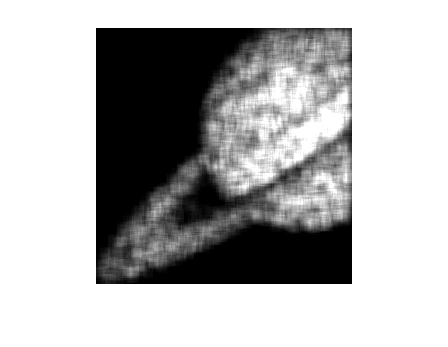

tempo=conv2(y,ones(10,10)/50,'same');
imshow(tempo);

down_siz=1/2;
disp(getPSNR(org_img,tempo));

   20.6821



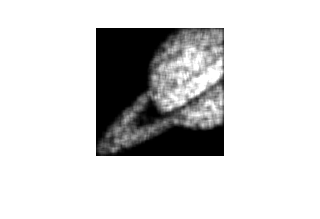

temp1=imresize(tempo,down_siz);
imshow(temp1);

disp(getPSNR(imresize(org_img,down_siz),temp1));

   21.0830



y_col=temp1(:);
dim=size(y_col,1);
u_0=zeros(dim,1);
v_0= temp1(:);
lambda=0.25;

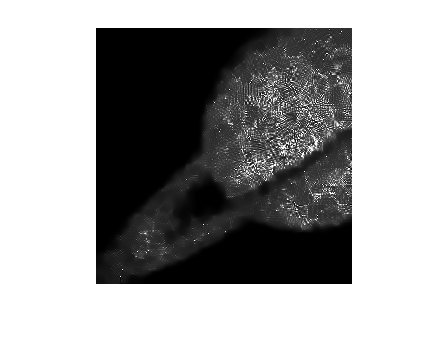

variance= var(y,0,'all');
% Call BM3D With the default settings.
est = BM3D(y, sqrt(variance));
imshow(est);

disp(getPSNR(org_img,est));

   11.2346



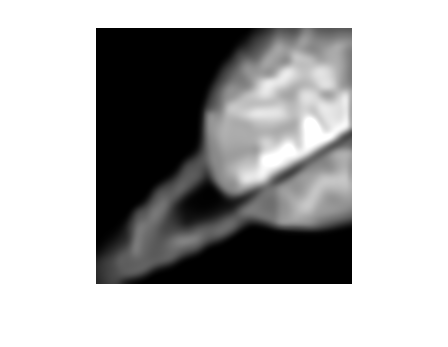

variance= var(temp1,0,'all');
% Call BM3D With the default settings.
est = BM3D(temp1, sqrt(variance));
%est = BM3D(y,2);
imshow(imresize(est,size(org_img)));

disp(getPSNR(org_img,imresize(est,size(org_img))))

   24.1673



%disp(getPSNR(imresize(org_img,down_siz),est));

beta=1;
epsilon=0.05;
tic
y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));

Printing the rrmse iter no while breaking the algo    54

    0.0488



toc

Elapsed time is 263.644761 seconds.


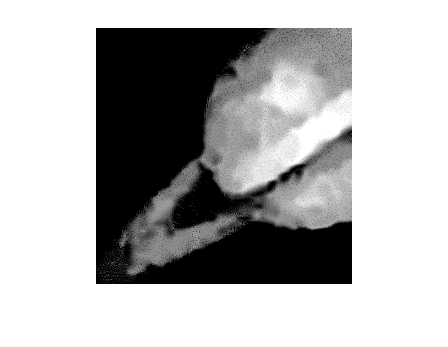

img_est=reshape(y_est,size(org_img));
figure;
imshow(img_est/peak);

disp(getPSNR(org_img,img_est))

   12.7427



beta=1;
epsilon=0.01;
tic
y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(temp1));

Printing the rrmse iter no while breaking the algo     9

    0.0078



toc

Elapsed time is 10.168644 seconds.


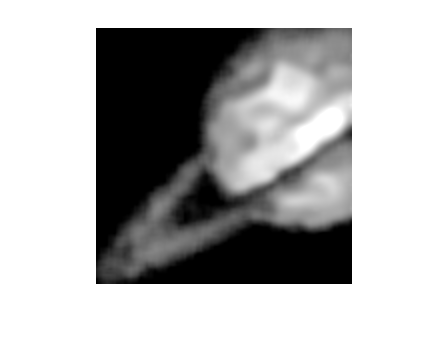

img_est=reshape(y_est,size(temp1));
figure;
imshow(imresize(img_est,size(org_img))); 

disp(getPSNR(org_img,imresize(img_est,size(org_img))))

   24.2343



list=zeros(6,1);
epsilon=0.01;
for i=1:6
    beta=10^(i-4);
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));
    t=reshape(y_est,size(y));
    list(i)=getPSNR(org_img,t);
end

Printing the rrmse iter no while breaking the algo     4

    0.0446

Printing the rrmse iter no while breaking the algo    58

    0.0486

Printing the rrmse iter no while breaking the algo    10

    0.0471

Printing the rrmse iter no while breaking the algo    70

    0.0814



figure
plot(-3:2,list);
xlabel("log_{10} beta");
ylabel("PSNR");

list=zeros(6,1);
epsilon=0.01;
for i=1:6
    beta=10^(i-4);
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(temp1));
    t=reshape(y_est,size(temp1));
    list(i)=getPSNR(org_img,imresize(t,size(org_img)));
end

Printing the rrmse iter no while breaking the algo     2

    0.0053

Printing the rrmse iter no while breaking the algo     3

    0.0055

Printing the rrmse iter no while breaking the algo     4

    0.0092

Printing the rrmse iter no while breaking the algo    10

    0.0095

Printing the rrmse iter no while breaking the algo     9

    0.0093

Printing the rrmse iter no while breaking the algo    10

    0.0097



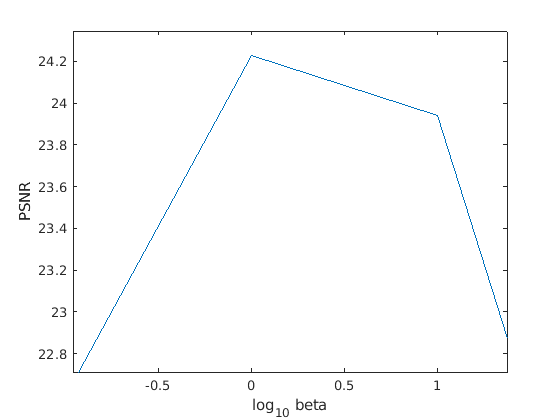

figure
plot(-3:2,list);
xlabel("log_{10} beta");
ylabel("PSNR");

list=zeros(20,1);
epsilon=0.01;
for i=1:20
    beta=0.5*i;
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(temp1));
    t=reshape(y_est,size(temp1));
    list(i)=getPSNR(org_img,imresize(t,size(org_img)));
end

Printing the rrmse iter no while breaking the algo     7

    0.0094

Printing the rrmse iter no while breaking the algo    10

    0.0095

Printing the rrmse iter no while breaking the algo     8

    0.0090

Printing the rrmse iter no while breaking the algo     8

    0.0095

Printing the rrmse iter no while breaking the algo     8

    0.0097

Printing the rrmse iter no while breaking the algo     8

    0.0096

Printing the rrmse iter no while breaking the algo     8

    0.0099

Printing the rrmse iter no while breaking the algo     8

    0.0099

Printing the rrmse iter no while breaking the algo     9

    0.0088

Printing the rrmse iter no while breaking the algo     9

    0.0088

Printing the rrmse iter no while breaking the algo     9

    0.0089

Printing the rrmse iter no while breaking the algo     9

    0.0089

Printing the rrmse iter no while breaking the algo     9

    0.0091

Printing the rrmse iter no while breaking the algo     9

    0.0092

Printing the rrmse i

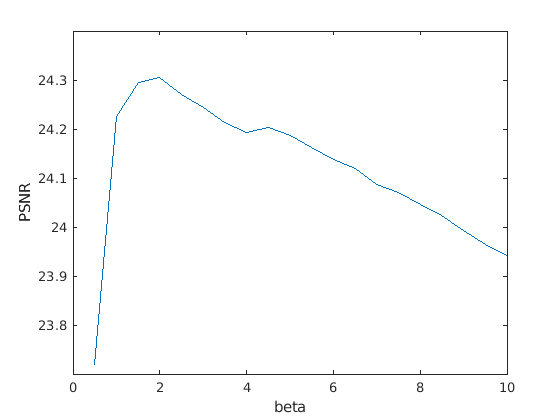

figure
plot(0.5:0.5:10,list);
xlabel("beta");
ylabel("PSNR");